## **Registro y visualizacion de datos**

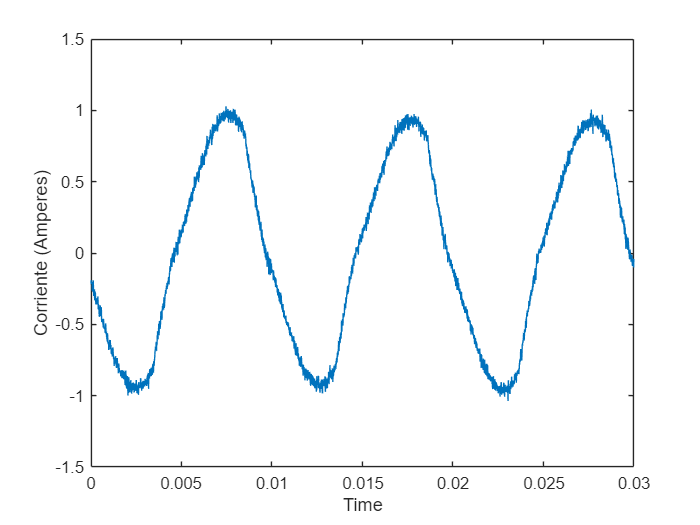

plot(Dev1_2_reducido.t_seconds, Dev1_2_reducido.Dev1_ai3)
xlabel("Time")
ylabel("Corriente (Amperes)")

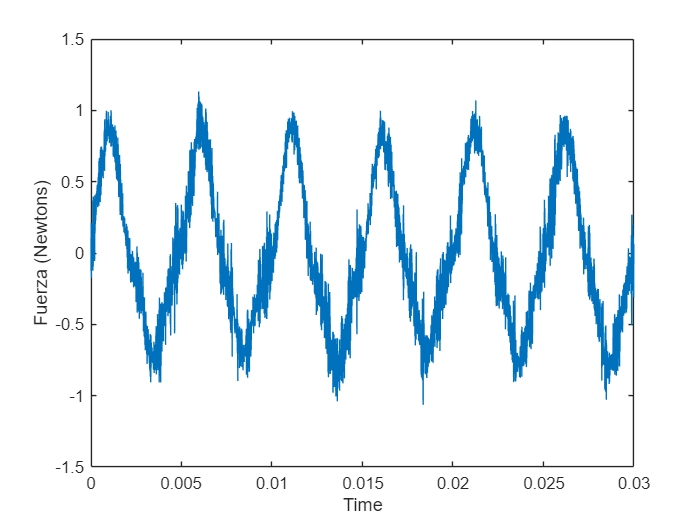


plot(Dev1_2_reducido.t_seconds, Dev1_2_reducido.Dev1_ai0)
xlabel("Time")
ylabel("Fuerza (Newtons)")

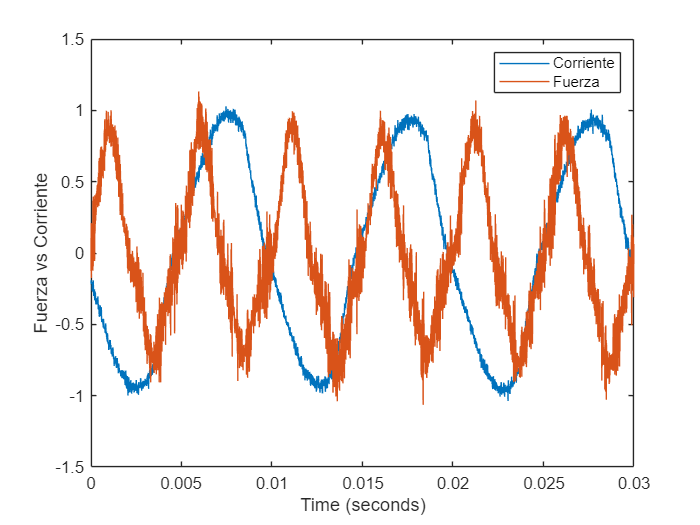


plot(Dev1_2_reducido.t_seconds, Dev1_2_reducido.Dev1_ai3, Dev1_2_reducido.t_seconds, Dev1_2_reducido.Dev1_ai0);
xlabel("Time (seconds)");
ylabel("Fuerza vs Corriente");
legend('Corriente', 'Fuerza');

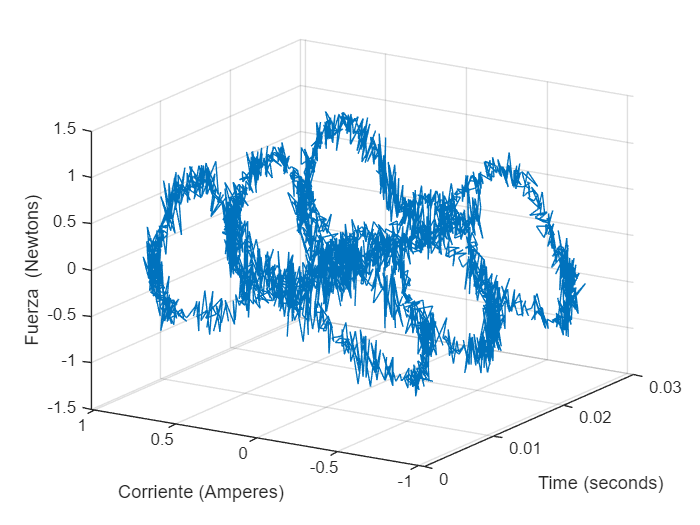

plot3(Dev1_2_reducido.t_seconds,Dev1_2_reducido.Dev1_ai3, Dev1_2_reducido.Dev1_ai0);
xlabel("Time (seconds)");
ylabel("Corriente (Amperes)");
zlabel("Fuerza  (Newtons)");
grid on;  % Encender la cuadrícula para una mejor visualización

view([-57.8595 21.3360])

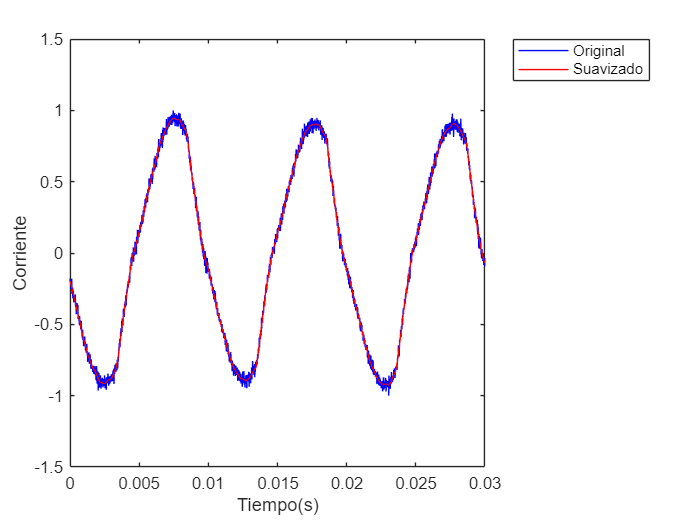


%view([-60.4586 26.7104])

CorrienteD = Dev1_2_reducido.Dev1_ai3;
FuerzaD = Dev1_2_reducido.Dev1_ai0;


% Encontrar el valor mínimo y máximo de los datos
minCurr = min(CorrienteD);
maxCurr = max(CorrienteD);

% Encontrar el valor mínimo y máximo de los datos
minForz = min(FuerzaD);
maxForz = max(FuerzaD);



%Fuerza =  (Dev1_2.Dev1_ai0(1:3000)- mean(Dev1_2.Dev1_ai0(1:3000)))/0.019;
%Corriente = (Dev1_2.Dev1_ai3(1:3000)- mean(Dev1_2.Dev1_ai3(1:3000)))/0.4;
Fuerza =  2 * ((FuerzaD - minForz) / (maxForz - minForz)) - 1;
Corriente = 2 * ((CorrienteD - minCurr) / (maxCurr - minCurr)) - 1;
t_seconds = Dev1_2_reducido.t_seconds;
Tiempo = t_seconds;



% Aplicar suavizado a las señales de Fuerza y Corriente
smooth_Fuerza = smoothdata(Fuerza, 'sgolay', 51);  % El tamaño de la ventana es un número impar
smooth_Corriente = smoothdata(Corriente, 'sgolay', 51);


plot(t_seconds, Corriente,'b',t_seconds,smooth_Corriente,'r')
xlabel("Tiempo(s)")
ylabel("Corriente")
legend('Original', 'Suavizado');
xlim([0.0000 0.0300])
ylim([-1.50 1.50])

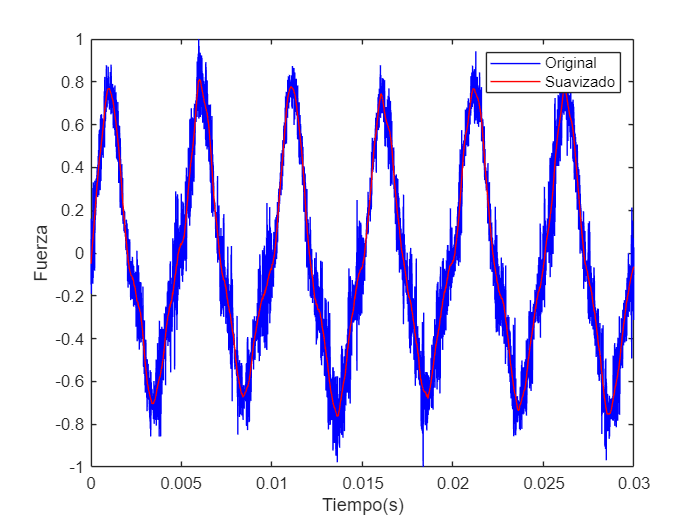



plot(t_seconds, Fuerza,'b',t_seconds,smooth_Fuerza,'r')
xlabel("Tiempo(s)")
ylabel("Fuerza")
legend('Original', 'Suavizado');

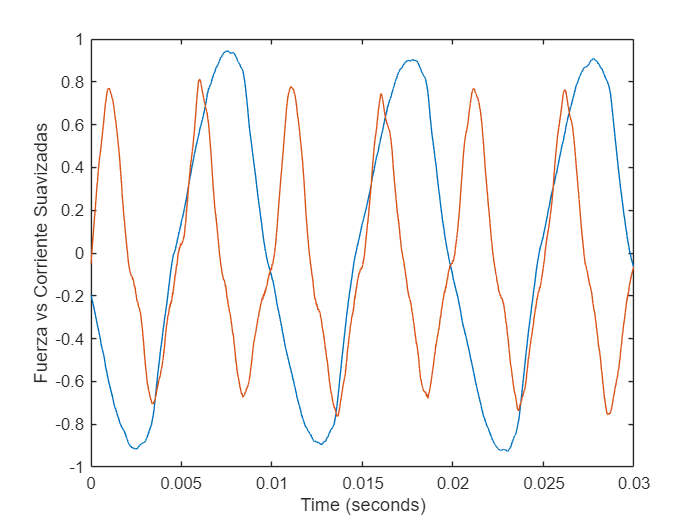



% Graficar los datos suavizados en 2D
plot(t_seconds, smooth_Corriente, t_seconds, smooth_Fuerza);
xlabel("Time (seconds)");
ylabel("Fuerza vs Corriente Suavizadas");

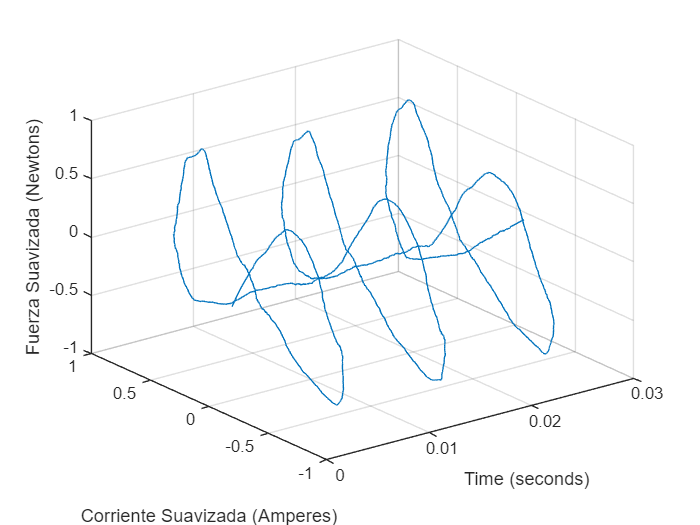




% Primera serie de datos
plot3(t_seconds, smooth_Corriente, smooth_Fuerza);
hold on;  % Mantener los ejes actuales y la figura para el siguiente plot


% Etiquetas y configuraciones del gráfico
xlabel("Time (seconds)");
ylabel("Corriente Suavizada (Amperes)");
zlabel("Fuerza Suavizada (Newtons)");
grid on;  % Encender la cuadrícula para una mejor visualización

% Finalizar la retención de los ejes para nuevas gráficas
hold off;

## Modelo Matematico de histeresis y ajuste no lineal de parametros

% Condiciones iniciales para los parámetros [A, B, C, n, k]
% Estos son valores iniciales arbitrarios para los parámetros


%x0 = [0.4351,0.7,0.06,0.18,0.35];
x0 = [1,0.5,0.5,2,1];

disp(x0)

    1.0000    0.5000    0.5000    2.0000    1.0000



% Opciones para lsqcurvefit (Opcional)
options = optimoptions('lsqcurvefit', 'Display', 'iter', 'Algorithm', 'trust-region-reflective');

% Ajuste de curvas no lineal para estimar los parámetros
[x_estimado, ~] = lsqcurvefit(@(x, t) bouc_wen_model(x, t, CorrienteD), x0, t_seconds, FuerzaD, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          6           774.013                              104
     1         12           774.013              10              104      
     2         18           774.013             2.5              104      
     3         24           774.013           0.625              104      
     4         30           726.272         0.15625              197      
     5         36           726.272          0.3125              197      
     6         42            696.19        0.078125              158      
     7         48            693.55         0.15625              234      
     8         54           687.383       0.0450825             79.8      
     9         60           687.326       0.0390625              119      
    10         66           685.508      0.00976562               45      
    11         72           684.924      


% Mostrar los parámetros estimados
disp('Parámetros estimados del modelo de Bouc-Wen:');

Parámetros estimados del modelo de Bouc-Wen:


disp(['A = ', num2str(x_estimado(1))]);

A = 0.86003


disp(['B = ', num2str(x_estimado(2))]);

B = 0.20377


disp(['C = ', num2str(x_estimado(3))]);

C = -0.47789


disp(['n = ', num2str(x_estimado(4))]);

n = 2.0163


disp(['k = ', num2str(x_estimado(5))]);

k = 1.0385


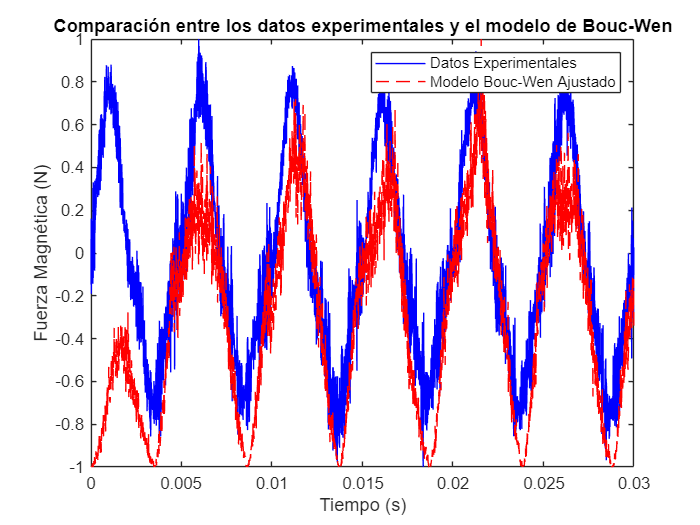

K_m = x_estimado(5);
% Utilizar los parámetros estimados para modelar la fuerza con los datos experimentales
[FuerzaModelada,Z] = bouc_wen_model(x_estimado, t_seconds, CorrienteD);


% Encontrar el valor mínimo y máximo de los datos
minForz = min(FuerzaModelada);
maxForz = max(FuerzaModelada);


FuerzaMod =  2 * ((FuerzaModelada - minForz) / (maxForz - minForz)) - 1;
smooth_histeresis = smoothdata(Z, 'sgolay', 51);


% Graficar los resultados
figure;
plot(t_seconds, Fuerza, 'b', t_seconds, FuerzaMod, 'r--');
title('Comparación entre los datos experimentales y el modelo de Bouc-Wen');
xlabel('Tiempo (s)');
ylabel('Fuerza Magnética (N)');
legend('Datos Experimentales', 'Modelo Bouc-Wen Ajustado');

## Modelo Bouc_Wen Fuerza Simulada

% Matriz de condiciones iniciales para x0
x0_matrix = [
    0.351, 0.7, 0.06, 0.58, 0.05;
    0.4351, 0.7, 0.06, 0.58, 0.04;
   % -0.04351, 0.8, -0.0126, 0.58, -0.02;
   % 1,0.5,0.5,2,1;
];

% Opciones para lsqcurvefit
options = optimoptions('lsqcurvefit', 'Display', 'iter', 'Algorithm', 'trust-region-reflective');

% Inicializar la figura para las curvas de histéresis
figure;
hold on; % Para múltiples gráficas

% Colores para diferenciar las simulaciones
colors = ['b', 'r', 'g', 'k', 'm']; % Asegúrate de tener suficientes colores para tus simulaciones

for i = 1:size(x0_matrix, 1)
    x0 = x0_matrix(i, :);
    
    % Ajuste de curvas no lineal para estimar los parámetros
    [x_estimado, ~] = lsqcurvefit(@(x, t) bouc_wen_model(x, t, CorrienteD), x0, t_seconds, FuerzaD, [], [], options);
    
    % Simulación del modelo de Bouc-Wen para el ciclo de corriente
    t_sim = linspace(0, 10, 1000); % Simular para 10 segundos
    I_sim =  sin(2 * pi * 100 * t_sim); % Generar ciclo de corriente
    FuerzaSimulada = zeros(size(t_sim));
    z_sim = 0; % Inicializar la variable de histéresis
    
    for k = 2:length(t_sim)
        du = (I_sim(k) - I_sim(k-1)) / (t_sim(k) - t_sim(k-1));
        z_sim = z_sim + (x_estimado(1) * du - x_estimado(2) * abs(du) * z_sim - x_estimado(3) * du * abs(z_sim)^x_estimado(4)) * (t_sim(k) - t_sim(k-1));
        FuerzaSimulada(k) = x_estimado(5) * z_sim^2;
    end

    % Graficar la curva de histéresis para las condiciones iniciales actuales
    plot(I_sim, FuerzaSimulada, colors(i), 'DisplayName', ['x0_' num2str(i)]);
end


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          6           809.378                             1.05
     1         12           809.378              10             1.05      
     2         18           809.378             2.5             1.05      
     3         24           801.632           0.625             23.6      
     4         30           801.632            1.25             23.6      
     5         36           742.893          0.3125              169      
     6         42           742.893           0.625              169      
     7         48           713.169         0.15625              358      
     8         54           713.169        0.158328              358      
     9         60           698.995       0.0390625             80.5      
    10         66           691.404       0.0390625             74.5      
    11         72           679.503      

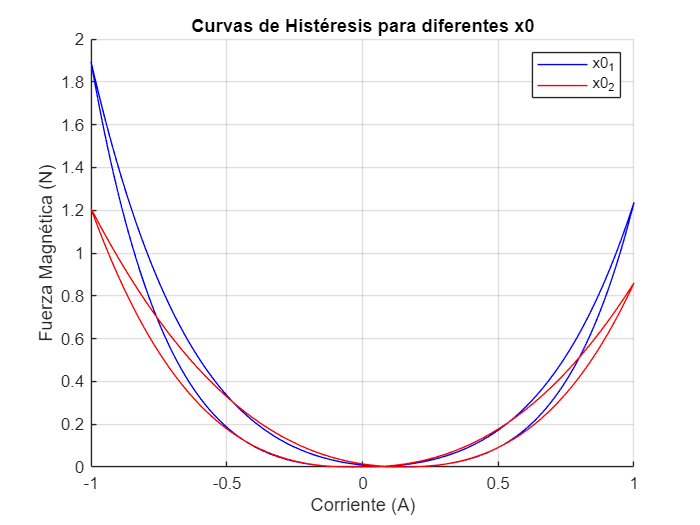


title('Curvas de Histéresis para diferentes x0');
xlabel('Corriente (A)');
ylabel('Fuerza Magnética (N)');
legend show;
grid on;
hold off; % Finalizar múltiples gráficas

## Modelo Bouc_Wen datos reales

% Matriz de condiciones iniciales para x0
x0_matrix = [
    0.2351, 0.7, 0.06, 0.58, 0.05;
    0.4351, 0.7, 0.06, 0.58, 0.04;
    0.4351, 0.7, 0.06, 0.58, 0.04;
];

% Opciones para lsqcurvefit
options = optimoptions('lsqcurvefit', 'Display', 'iter', 'Algorithm', 'trust-region-reflective');

% Inicializar la figura para las curvas de histéresis
figure;
hold on; % Para múltiples gráficas

% Colores para diferenciar las simulaciones
colors = ['b', 'r', 'g', 'k', 'm']; % Asegúrate de tener suficientes colores para tus simulaciones

for i = 1:size(x0_matrix, 1)
    x0 = x0_matrix(i, :);
    
    % Ajuste de curvas no lineal para estimar los parámetros con datos reales
    [x_estimado, ~] = lsqcurvefit(@(x, t) bouc_wen_model(x, t, CorrienteD), x0, t_seconds, FuerzaD, [], [], options);
    
    % Utiliza los parámetros estimados para simular la respuesta de fuerza basada en la corriente real
    [FuerzaSimulada,Zr] = bouc_wen_model(x_estimado, t_seconds, CorrienteD);
    
    % Graficar la curva de histéresis para las condiciones iniciales actuales usando datos reales
    plot(CorrienteD, FuerzaSimulada, colors(i), 'DisplayName', ['x0_' num2str(i)]);
end


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          6           809.436                            0.469
     1         12           809.436              10            0.469      
     2         18           809.436             2.5            0.469      
     3         24           803.384           0.625             18.3      
     4         30           803.384            1.25             18.3      
     5         36           754.502          0.3125              149      
     6         42           754.502           0.625              149      
     7         48           709.492         0.15625              135      
     8         54           709.492          0.3125              135      
     9         60           704.839        0.078125              157      
    10         66            697.98       0.0195312              108      
    11         72           690.496      

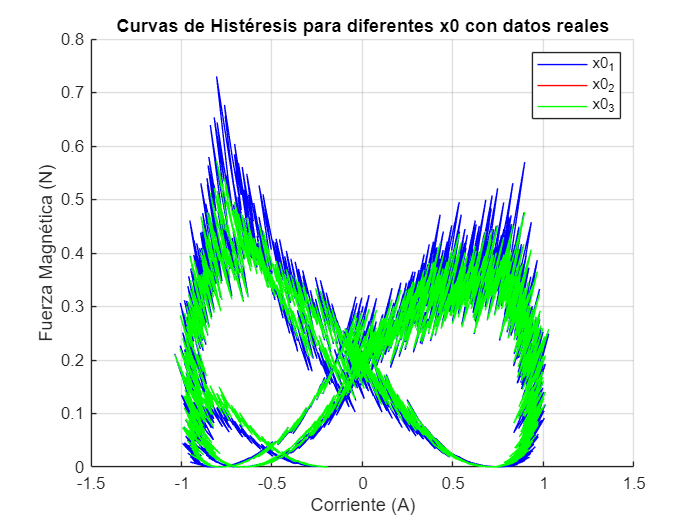


title('Curvas de Histéresis para diferentes x0 con datos reales');
xlabel('Corriente (A)');
ylabel('Fuerza Magnética (N)');
legend show;
grid on;
hold off; % Finalizar múltiples gráficas

## Modelo de Fuerza

F_m = modelo_cojinete(smooth_Corriente,K_m);
%F_m = FuerzaSimulada;

%H = smooth_histeresis; % Asegúrate de que esto es un vector columna
H = Z;
time = t_seconds; % Asegúrate de que esto es un vector columna


% Calcular la derivada de H respecto a t
dH_dt = [0; diff(H)./diff(time)]; % Prepend un cero para hacer el vector del mismo tamaño

% Ahora define el modelo de Duhem con la derivada incluida
duhem_model = @(p, H, dH_dt) p(1)*H + p(2)*H.^2 + p(3)*H.^3 + p(4)*dH_dt;

% Parámetros iniciales [a, b, c, ...]
p0 = [0.033, -0.2, 0.01, 0.1]; % Valores iniciales estimados para los parámetros

% Ajuste de parámetros con lsqcurvefit
options = optimoptions('lsqcurvefit','Display','iter');
[p_fit, ~, ~] = lsqcurvefit(@(p, x) duhem_model(p, H(x), dH_dt(x)), p0, (1:length(H))', F_m, [], [], options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          5        3.2763e+08                         3.28e+09
     1         10           515.205         1.79887            0.588      
     2         15           515.205     2.64249e-06         9.53e-08      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


disp(p_fit)

   -0.1429    1.5380    0.4276   -0.0000



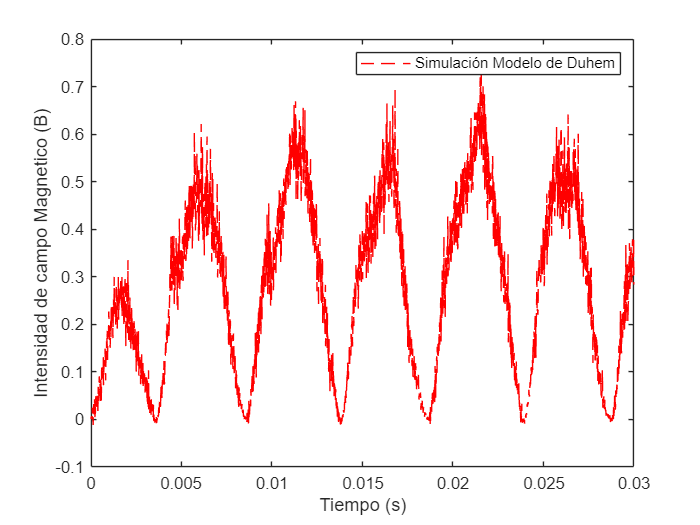

% Simula el modelo con los parámetros ajustados y compara con los datos experimentales
B_fit = duhem_model(p_fit, H, dH_dt);
% Calcula la fuerza magnética con el modelo ajustado
%F_m_ajustada = K_m*smooth_Corriente.^2 + B_fit;
% Definir las constantes y parámetros iniciales del modelo
mu_0 = 4 * pi * 1e-7; % Permeabilidad del espacio libre (H/m)
N = 200; % Número de vueltas de la bobina
S = pi * (8.7173)^2; % Área de la sección transversal del núcleo (m^2)
% Km = N^2*mu_0*S/4;
% Km = 2;
Km = x_estimado(5);
F_m_ajustada = Km*B_fit.^2;
% Visualización
figure;
plot(time, B_fit, 'r--', 'DisplayName', 'Simulación Modelo de Duhem');
xlabel('Tiempo (s)');
ylabel('Intensidad de campo Magnetico (B)');
legend show;

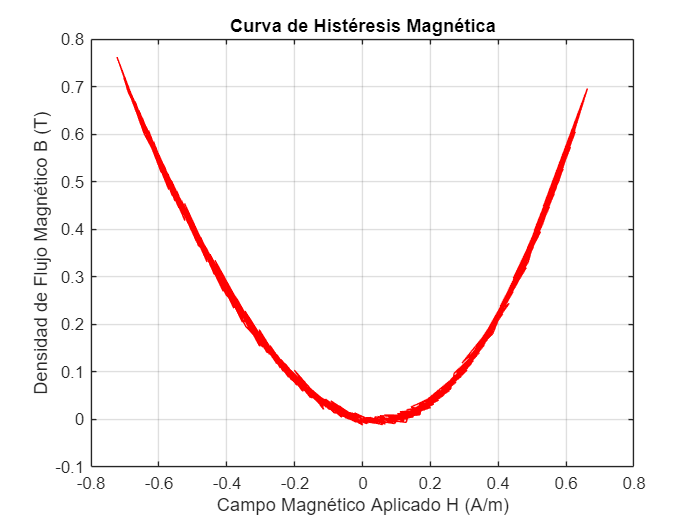


% Graficar B vs H para observar el comportamiento histérico
figure;
plot(H, B_fit, 'r-');
xlabel('Campo Magnético Aplicado H (A/m)');
ylabel('Densidad de Flujo Magnético B (T)');
title('Curva de Histéresis Magnética');
grid on;

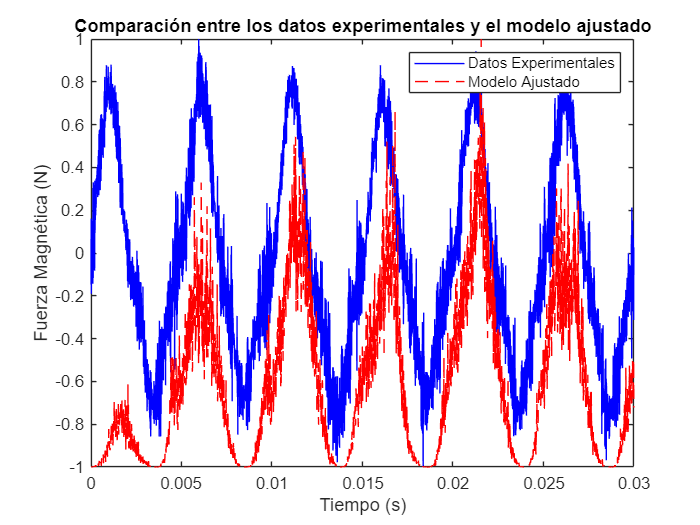


minForzN = min(F_m_ajustada);
maxForzN = max(F_m_ajustada);

FuerzaModN =  2 * ((F_m_ajustada - minForzN) / (maxForzN - minForzN)) - 1;
% Visualización de la fuerza magnética
figure;
plot(t_seconds, Fuerza, 'b', t_seconds, FuerzaModN, 'r--');
xlabel('Tiempo (s)');
ylabel('Fuerza Magnética (N)');
title('Comparación entre los datos experimentales y el modelo ajustado');
legend('Datos Experimentales', 'Modelo Ajustado');

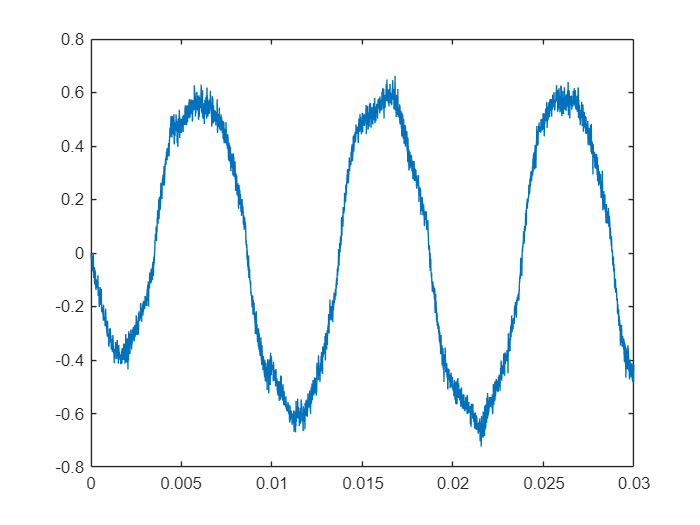

figure;
plot(t_seconds,H)

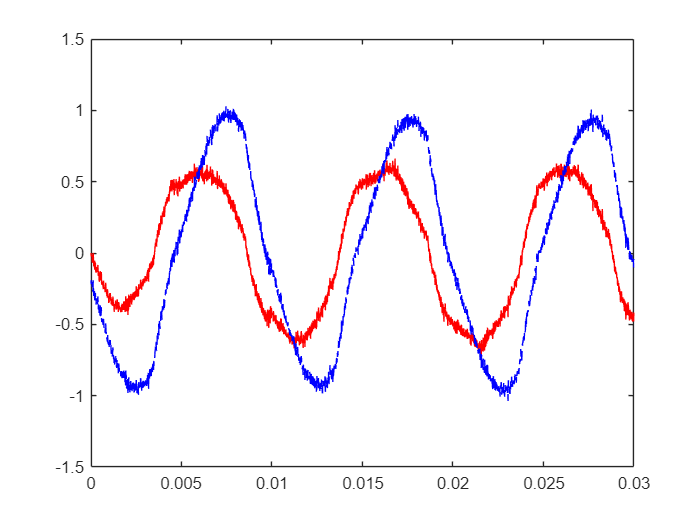

plot(t_seconds,H,'r',t_seconds,CorrienteD,'b--')

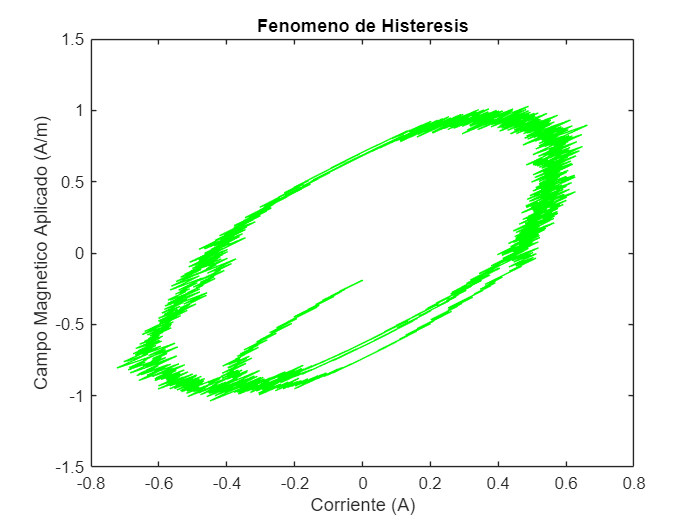

figure;
plot(H,smooth_Corriente,'g')
xlabel('Corriente (A)');
ylabel('Campo Magnetico Aplicado (A/m)');
title('Fenomeno de Histeresis');

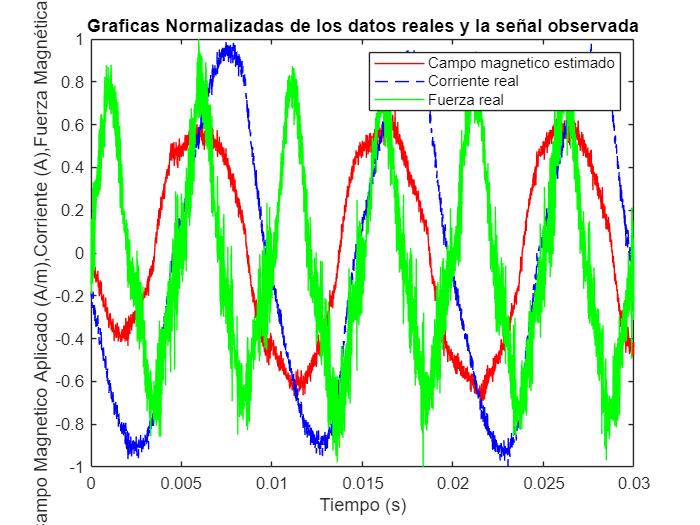

figure;
plot(t_seconds,H,'r',t_seconds,Corriente,'b--',t_seconds,Fuerza,'g')
xlabel('Tiempo (s)');
ylabel('Campo Magnetico Aplicado (A/m),Corriente (A),Fuerza Magnética (N)');
title('Graficas Normalizadas de los datos reales y la señal observada');
legend('Campo magnetico estimado','Corriente real','Fuerza real');

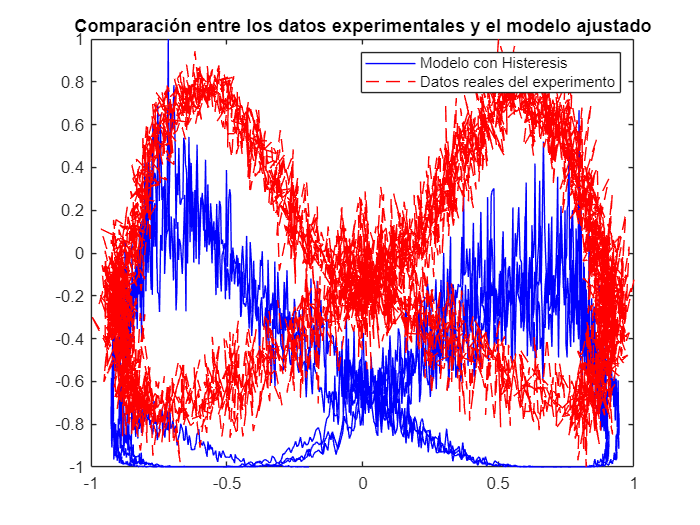

figure;
plot(smooth_Corriente,FuerzaModN,'b',Corriente,Fuerza,'r--')
title('Comparación entre los datos experimentales y el modelo ajustado');
legend('Modelo con Histeresis','Datos reales del experimento');

## Generador de Casos basado en modelo

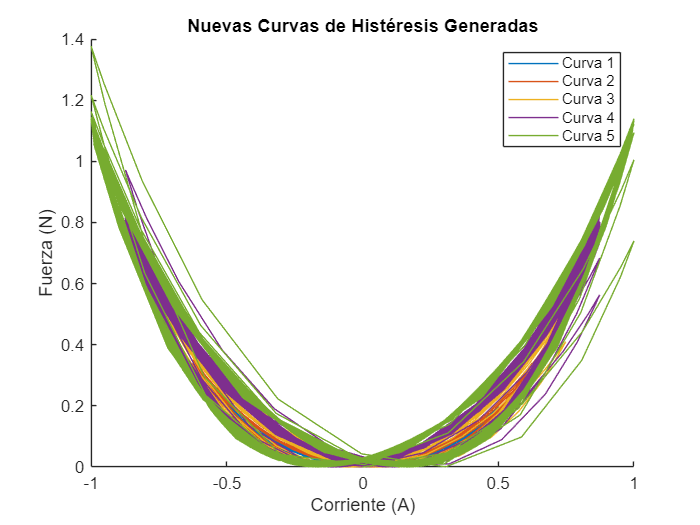

%% Definición de Parámetros
% Número de curvas de histéresis que deseas generar
num_curvas = 5;
amplitud_corriente = linspace(0.5, 1, num_curvas);  % Diferentes amplitudes de corriente
frecuencia_corriente = linspace(1, 5, num_curvas);  % Diferentes frecuencias

% Vector de tiempo
t_seconds = linspace(0, 10, 1000)'; % Vector de tiempo de 0 a 10 segundos con 1000 puntos

% Tamaño total para preasignar
n_puntos = length(t_seconds); % 1000
n_total = num_curvas * n_puntos;

% Preasignar las variables
nuevas_corrientes = zeros(n_total, 1);
nuevas_fuerzas = zeros(n_total, 1);
nuevas_histeresis = zeros(n_total, 1);

%% Generar Nuevas Curvas de Histéresis
figure;
hold on;

for i = 1:num_curvas
    % Cálculo de la nueva corriente
    nueva_corriente = amplitud_corriente(i) * sin(2 * pi * frecuencia_corriente(i) * t_seconds);
    
    % Cálculo de la nueva fuerza y histéresis utilizando el modelo de Bouc-Wen
    [nueva_fuerza, nueva_histere] = bouc_wen_model(x_estimado, t_seconds, nueva_corriente);
    
    % Graficar la curva actual
    plot(nueva_corriente, nueva_fuerza);
    
    % Índices para almacenar los datos en las variables preasignadas
    indice_inicio = (i-1)*n_puntos + 1;
    indice_fin = i*n_puntos;
    
    % Asignación directa en las variables preasignadas
    nuevas_corrientes(indice_inicio:indice_fin) = nueva_corriente;
    nuevas_fuerzas(indice_inicio:indice_fin) = nueva_fuerza;
    nuevas_histeresis(indice_inicio:indice_fin) = nueva_histere;
end

xlabel('Corriente (A)');
ylabel('Fuerza (N)');
legend('Curva 1', 'Curva 2', 'Curva 3', 'Curva 4', 'Curva 5');
title('Nuevas Curvas de Histéresis Generadas');

hold off;


%% Almacenar las Nuevas Curvas en la Tabla de Casos
% Crear una tabla con los nuevos casos
nuevas_casos = table(repmat(t_seconds, num_curvas, 1), nuevas_corrientes, nuevas_fuerzas, nuevas_histeresis, ...
    'VariableNames', {'Tiempo', 'Corriente', 'Fuerza', 'Histeresis'});



## Modelos de dunhem 


%% Ajuste del Modelo de Duhem a las Nuevas Curvas
% Parámetros iniciales [a, b, c, d]
p0 = [0.033, -0.2, 0.01, 0.1];

% Opciones para lsqcurvefit
options = optimoptions('lsqcurvefit','Display','iter');

% Preasignar matrices para almacenar los parámetros ajustados y las fuerzas simuladas
parametros_ajustados = zeros(num_curvas, length(p0));
F_duhem_fit_all = zeros(num_curvas * n_puntos, 1);

figure;

for i = 1:num_curvas
    % Índices para extraer y almacenar los datos
    indice_inicio = (i-1)*n_puntos + 1;
    indice_fin = i*n_puntos;
    
    % Extraer la curva de histéresis correspondiente
    H = nuevas_histeresis(indice_inicio:indice_fin); % Histéresis para la curva i
    time = t_seconds; % Vector de tiempo
    
    % Calcular la derivada de H respecto a t
    dH_dt = [0; diff(H)./diff(time)]; % Prepend un cero para igualar el tamaño
    
    % F_m es la fuerza correspondiente a esta curva
    F_m = nuevas_fuerzas(indice_inicio:indice_fin);
    
    % Ajuste de parámetros con lsqcurvefit
    x_indices = (1:length(H))';
    
    [p_fit_i, ~, ~] = lsqcurvefit(@(p, x) duhem_model(p, H(x), dH_dt(x)), p0, x_indices, F_m, [], [], options);
    
    % Almacenar los parámetros ajustados
    parametros_ajustados(i, :) = p_fit_i;
    
    % Simular el modelo con los parámetros ajustados
    F_duhem_fit = duhem_model(p_fit_i, H, dH_dt);
    F_duhem_fit_all(indice_inicio:indice_fin) = F_duhem_fit;
    
    % Graficar la fuerza original y la fuerza ajustada
    subplot(num_curvas, 1, i);
    plot(time, F_m, 'b', 'DisplayName', 'Fuerza Original');
    hold on;
    plot(time, F_duhem_fit, 'r--', 'DisplayName', 'Fuerza Ajustada (Duhem)');
    xlabel('Tiempo (s)');
    ylabel('Fuerza (N)');
    title(['Curva ', num2str(i)]);
    legend;
    hold off;
end


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          5           64.1235                              427
     1         10       7.60691e-18         1.08712         5.08e-08      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          5           351.952      

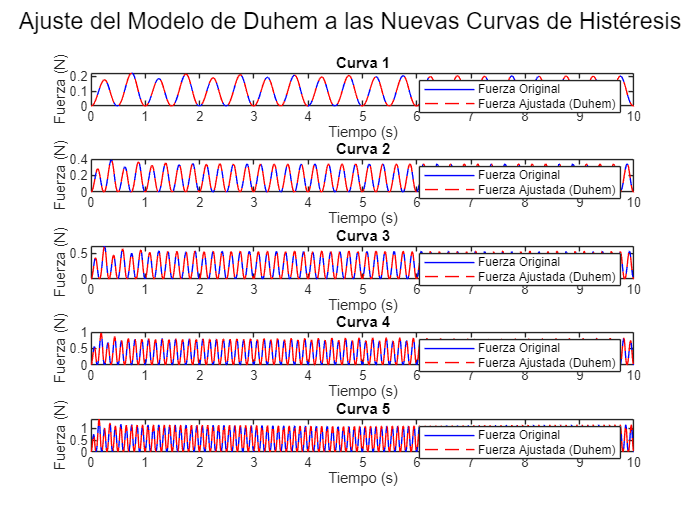


sgtitle('Ajuste del Modelo de Duhem a las Nuevas Curvas de Histéresis');

## Curvas de Histeresis de los casos generados

%% Almacenar las Nuevas Curvas en la Estructura de Casos
% Crear una estructura para almacenar los casos
casos = struct();

% En tu bucle principal
for i = 1:num_curvas
    % Índices para extraer los datos
    indice_inicio = (i-1)*n_puntos + 1;
    indice_fin = i*n_puntos;
    
    % Crear caso usando la función
    casos(i) = crear_caso
        t_seconds,
        nuevas_corrientes(indice_inicio:indice_fin),
        nuevas_fuerzas(indice_inicio:indice_fin),
        nuevas_histeresis(indice_inicio:indice_fin),
        amplitud_corriente(i),
        frecuencia_corriente(i)
end

Not enough input arguments.

Error in crear_caso (line 4)
    caso.tiempo = tiempo;


%% Graficar Todas las Curvas de Histéresis en una Sola Figura
figure;
hold on;
for i = 1:num_curvas
    plot(casos(i).corriente, casos(i).histeresis, 'DisplayName', ['Curva ' num2str(i)]);
end
xlabel('Corriente (A)');
ylabel('Campo Magnético Aplicado (A/m)');
title('Fenómeno de Histéresis');
legend('show');
hold off;


## Analisis de fourier

`plot(t_seconds, H, 'r', t_seconds, CorrienteD, 'b--', t_seconds, FuerzaD, 'g');`

`xlabel('Tiempo (s)');`

`ylabel('Campo Magnético Aplicado (A/m), Corriente (A), Fuerza Magnética (N)');`

`title('Comparación entre los datos experimentales y el modelo ajustado');`

`legend('Datos Experimentales', 'Modelo Ajustado');`

fs = 100000; % Frecuencia de muestreo

% FFT de la señal de corriente
fft_Corriente = fft(smooth_Corriente);
frequencies = linspace(0, fs/2, length(smooth_Corriente)/2+1);  % Frecuencias hasta la frecuencia de Nyquist

% Graficar el espectro de la señal de corriente (solo la mitad debido a la simetría)
figure;
plot(frequencies(1:30), abs(fft_Corriente(1:30)));
title('Espectro de Frecuencia de la Corriente');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');

% señal de fuerza
fft_Fuerza = fft(smooth_Fuerza);
frequencies = linspace(0, fs/2, length(smooth_Fuerza)/2+1);  % Frecuencias hasta la frecuencia de Nyquist

% Graficar el espectro de la señal de corriente (solo la mitad debido a la simetría)
figure;
plot(frequencies(1:30), abs(fft_Fuerza(1:30)));
title('Espectro de Frecuencia de la Fuerza');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');


% señal de fuerza
fft_H = fft(H);
frequencies = linspace(0, fs/2, length(H)/2+1);  % Frecuencias hasta la frecuencia de Nyquist

% Graficar el espectro de la señal de corriente (solo la mitad debido a la simetría)
figure;
plot(frequencies(1:30), abs(fft_H(1:30)));
title('Espectro de Frecuencia del flujo magnetico');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');

## Tiempo de respuesta del modelo con observador de posición

load('datos_observador.mat')
load('datos_observador_sin_histeresis.mat')
figure;
plot(t, ye, 'b', t, ye_s, 'r'); % Gráfica de las respuestas
title('Respuesta dinámica cojinete magnético');
xlabel('tiempo (s)');
ylabel('posición');

% Cálculos para la respuesta con histéresis
valor_final_ye = ye(end); 
rango_error_ye = valor_final_ye * 0.05; 
indice_respuesta_ye = find(abs(ye - valor_final_ye) <= rango_error_ye, 1, 'first');
tiempo_respuesta_ye = t(indice_respuesta_ye);

% Cálculos para la respuesta sin histéresis
valor_final_ye_s = ye_s(end); 
rango_error_ye_s = valor_final_ye_s * 0.05; 
indice_respuesta_ye_s = find(abs(ye_s - valor_final_ye_s) <= rango_error_ye_s, 1, 'first');
tiempo_respuesta_ye_s = t(indice_respuesta_ye_s);

% Agrega las líneas verticales para los tiempos de respuesta
hold on; 
line([tiempo_respuesta_ye tiempo_respuesta_ye], ylim, 'Color', 'k', 'LineStyle', '--');
line([tiempo_respuesta_ye_s tiempo_respuesta_ye_s], ylim, 'Color', 'g', 'LineStyle', '--');
hold off; 

% Agrega la leyenda con las descripciones deseadas
legend({'Modelo con Histéresis', 'Modelo sin Histéresis', ...
        ['Tiempo de respuesta con histéresis: ' num2str(tiempo_respuesta_ye) ' s'], ...
        ['Tiempo de respuesta sin histéresis: ' num2str(tiempo_respuesta_ye_s) ' s']}, ...
        'Location', 'best');

grid on;
